# Práctica 2: Análisis de métodos de control de complejidad

## Abstract

Estudio estadístico que analiza el comportamiento de  los métodos de selección de modelos. Comparando k-CV, Bootstrap, y los métodos de penalización AIC y AICC. Utiliza la familia de funciones polinomiales  como funciones aproximadoras.

## Conjunto de datos

## Generación de datos teóricos (Población)

Para generar la función teórica se ha generado una muestra de 1000 ejemplos. Con ella calcularemos el ruido que usaremos para generar las muestras para realizar los experimentos.

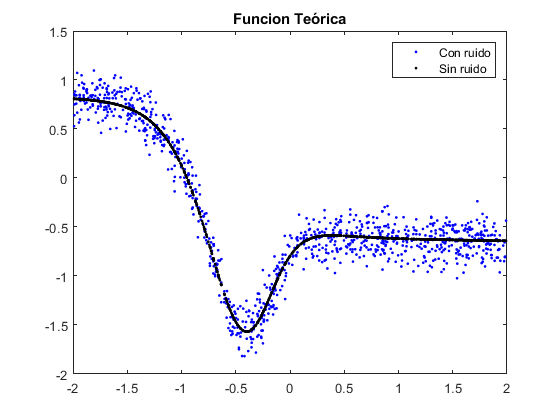

clear all,close all,clc,warning('off','all');

num_points = 1000;

%Definimos x e y.
x=4*(rand(1,num_points)-0.5);
yok=1.8 *tanh(3.2 * x + 0.8)- 2.5 * tanh(2.1 * x + 1.2)-0.2 * tanh(0.1 * x-0.5); 

%Definimos ruido y se lo añadimos a nuestra y.
RUIDO=0.2 * std(yok);
yruido=RUIDO * randn(size(yok));
y=yok+yruido;

plot(x,y,'.b'); hold on
plot(x,yok,'.k');  hold off
legend('Con ruido','Sin ruido');
title('Funcion Teórica')

## Métodos de remuestreo

## k-Cross-Validation

Uno de los métodos que usaremos será *k-cross-validation* , donde dividiremos la muestra en *k* partes iguales y donde usaremos una de ellas para validar el modelo y las *k* restantes para entrenarlo. El valor típico de *k* suele ser 10, aunque encontrar el *k* óptimo dependerá totalmente de nuestra muestra y representatividad de nuestros datos con respecto a la función subyacente.

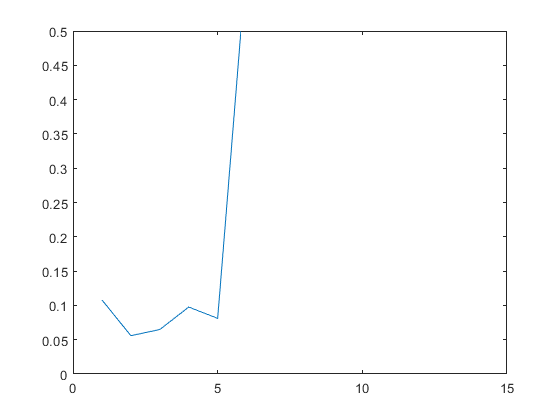

n_sample = 30;
max_complex = 15;
n_experiments = 100;

for t=1:n_experiments
    
    index = randperm(1000, n_sample);
    xsample = x(index);
    ysample = y(index);
    
    if t == 1
        c = cvpartition(n_sample,'KFold',10);
        cnew = c;
    end

    for i=1:max_complex
        fun = @(xTrain,yTrain,xTest,yTest)(mse(yTest - polyval(polyfit(xTrain, yTrain, i), xTest))); 
        cv_error(t, i) = sum(crossval(fun,xsample',ysample' ,'partition',cnew))/sum(cnew.TestSize);
    end
    
    cnew = repartition(c);    
    [~ , best_model] = min(cv_error(t, :));
    best_local_model(t) = best_model;
end

plot(1:max_complex, mean(cv_error))
xlim([0, 15])
ylim([0, 0.5])

## Bootstrap

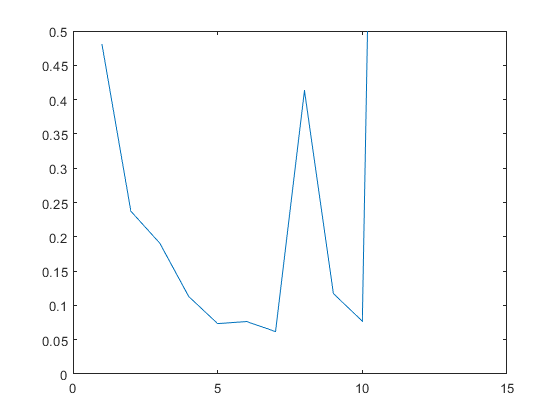

n_sample = 30;
index = randperm(1000, n_sample);
max_complex = 15;
n_experiments = 100;

for t=1:n_experiments
    
    xsample = x(index);
    ysample = y(index);
    
    size_boostrap_sample = 30;
    n_bootstrap_samples = 25;
      
    [~, train_index] = bootstrp(1, @mean, xsample(1:size_boostrap_sample));
    xTrain = xsample(train_index);
    yTrain = ysample(train_index);
    
    aux=1;
    for i=i:length(train_index)
       if find(i==train_index)
          xtest(aux)=xsample(i); 
          ytest(aux)=ysample(i);
          aux=aux+1;
       end
    end
        
    for i=1:max_complex
        model = polyfit(xTrain, yTrain, i);
        bootstrap_error(t, i) = mse(ytest, polyval(model, xtest));
    end 
    
    [~ , best_model] = min(bootstrap_error(t, :));
    best_local_model_bt(t) = best_model;
end


plot(1:max_complex, mean(bootstrap_error))
xlim([0, 15])
ylim([0, 0.5])

## Distribución de los modelos haciendo uso de métodos de remuestreo

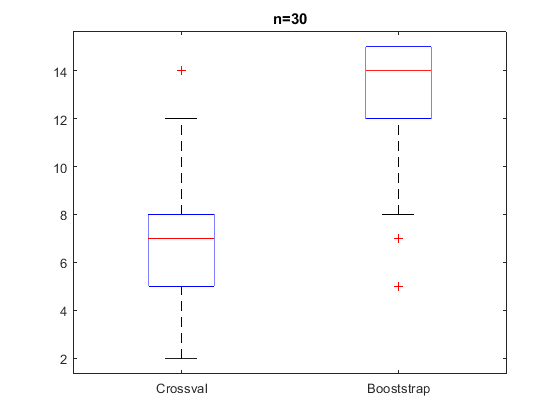

boxplot([best_local_model', best_local_model_bt'],{'Crossval','Booststrap'})
title(['n=',num2str(30)])

## Métodos de penalización

## AICC y AIC

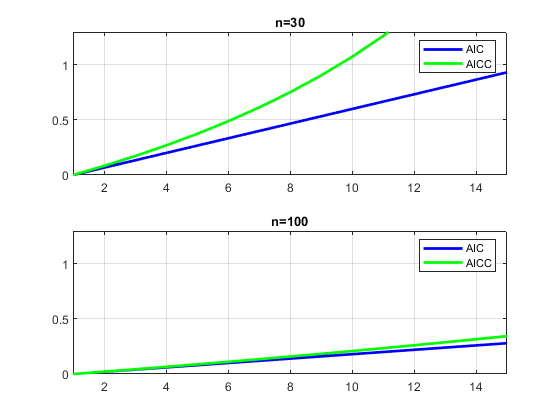

n = 30;
 
k=1:15;
AIC=2*(k+1)./n;
AICC=(n+k)./(n-k-2);

AIC=AIC-AIC(1);
AICC=AICC-AICC(1);

subplot(2,1,1);
plot(k,AIC,'-b','LineWidth',2),hold on;
plot(k,AICC,'-g','LineWidth',2),hold off;
legend('AIC','AICC'),grid;
axis([1,15,0,1.3])
title(['n=',num2str(n)])

n = 100;
 
k=1:15;
AIC=2*(k+1)./n;
AICC=(n+k)./(n-k-2);

AIC=AIC-AIC(1);
AICC=AICC-AICC(1);

subplot(2,1,2);
plot(k,AIC,'-b','LineWidth',2),hold on;
plot(k,AICC,'-g','LineWidth',2),hold off;
legend('AIC','AICC'),grid;
axis([1,15,0,1.3])
title(['n=',num2str(n)])

## AIC

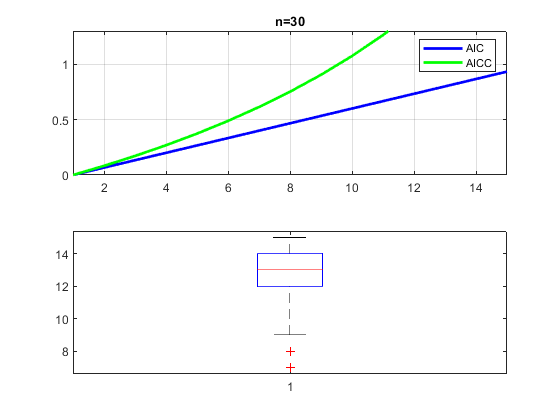

n_sample = 100;
max_complex = 15;
n_experiments = 100;

k=1:max_complex;
AIC=2*(k+1)./n_sample;

for t=1:n_experiments
    index = randperm(1000, n_sample);   
    xtrain = x(index);
    ytrain = y(index);
    
    index = randperm(1000, n_sample);   
    xtest = x(index);
    ytest = y(index);
    
    for i=1:max_complex
        model = polyfit(xtrain, ytrain, i);
        e_error(t, i) = mse(ytest, polyval(model, xtest));
    end
    
    aic_error(t, :) = log(e_error(t, :)) + AIC;
    
   [~ , best_model] = min(aic_error(t, :));
   best_local_model_aic(t) = best_model;
end

plot(1:max_complex, mean(aic_error))
xlim([0, 15])
ylim([0, 0.5])

boxplot(best_local_model_aic)

## AICc

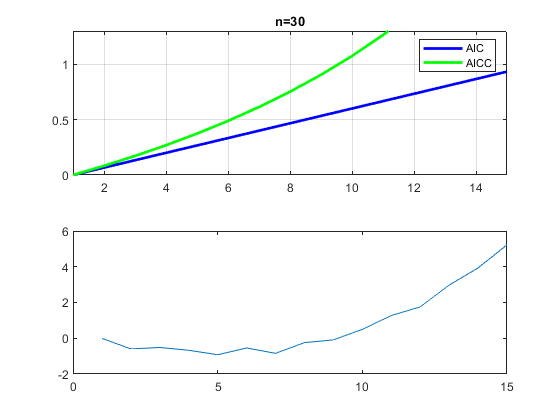

n_sample = 30;
max_complex = 15;
n_experiments = 100;

k=1:max_complex;
AICC=(n_sample+k)./(n_sample-k-2);

for t=1:n_experiments
    index = randperm(1000, n_sample);   
    xtrain = x(index);
    ytrain = y(index);
    
    index = randperm(1000, n_sample);   
    xtest = x(index);
    ytest = y(index);
    
    for i=1:max_complex
        model = polyfit(xtrain, ytrain, i);
        e_error(t, i) = mse(ytest, polyval(model, xtest));
    end
    
    aicc_error(t, :) = log(e_error(t, :)) + AICC;
    
   [~ , best_model] = min(aicc_error(t, :));
   best_local_model_aicc(t) = best_model;
end

plot(1:max_complex, mean(aicc_error))
xlim([0, 15])

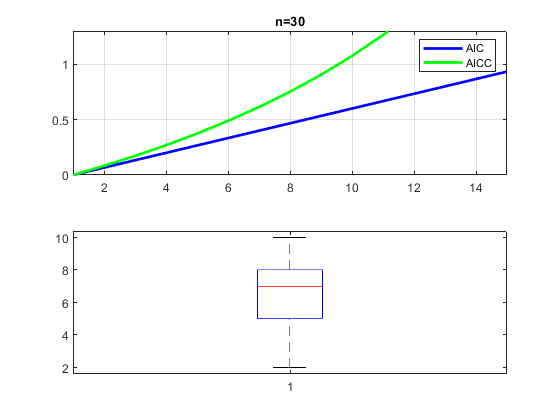


boxplot(best_local_model_aicc)

**Ahora veámoslo todo junto.**

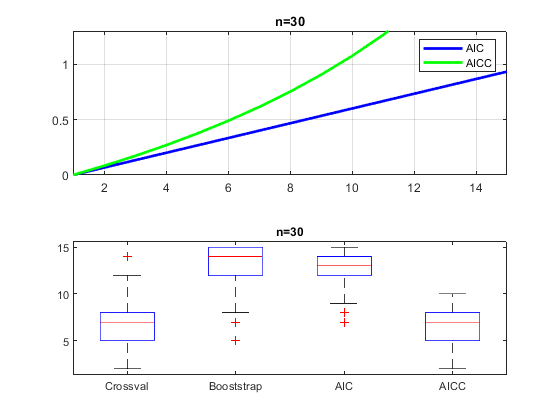

 boxplot([best_local_model', best_local_model_bt',best_local_model_aic',best_local_model_aicc'],{'Crossval','Booststrap','AIC','AICC'})
 title(['n=',num2str(30)])